# Tutorial for interpolation and feature detection written by Chris McIntosh ([chris.mcintosh@rmp.uhn.on.ca](mailto:chris.mcintosh@rmp.uhn.on.ca))

close all; clear all;

## Interpolation 1D - How do the results change with the frequency of the sinusoid?

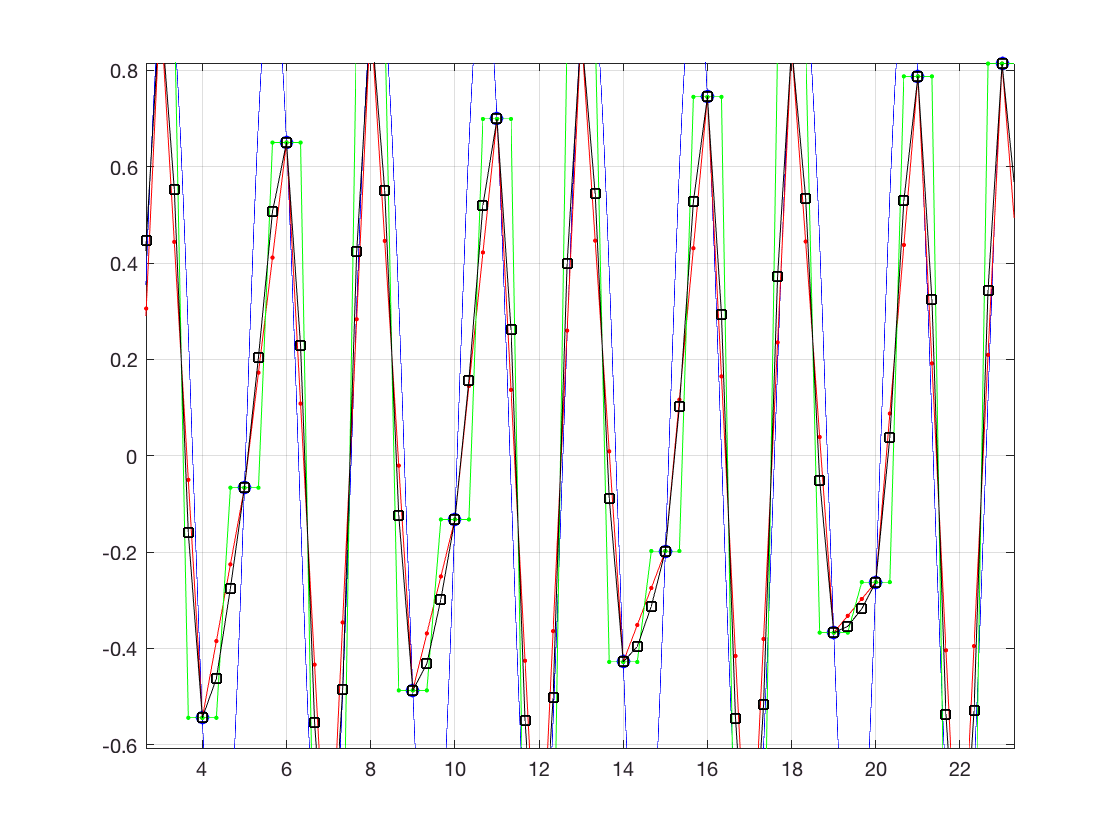

p = 2.5;
x0 = 1:0.001:30;
xi = 1:1:30;
f = sin(p*xi);
fx0 = sin(p*x0);
figure;plot(x0,fx0,'b');axis tight;grid on;hold on;
plot(xi,f,'bo');

%compute a 1D interpolation kernel and perform interp via convolution
xii = 1:1/3:30;
linHx = [0 1/3 2/3 1 2/3 1/3 0];
fL = zeros(1,numel(f)*3-2);
fL(1:3:end) = f;%Fill in the integer-location values
plot(xii,conv(fL,linHx,'same'),'r.-');

%Compute some other methods
plot(xii,interp1(xi,f,xii,'nearest'),'g.-');
plot(xii,interp1(xi,f,xii,'cubic'),'ks-');

## Decimation 2D

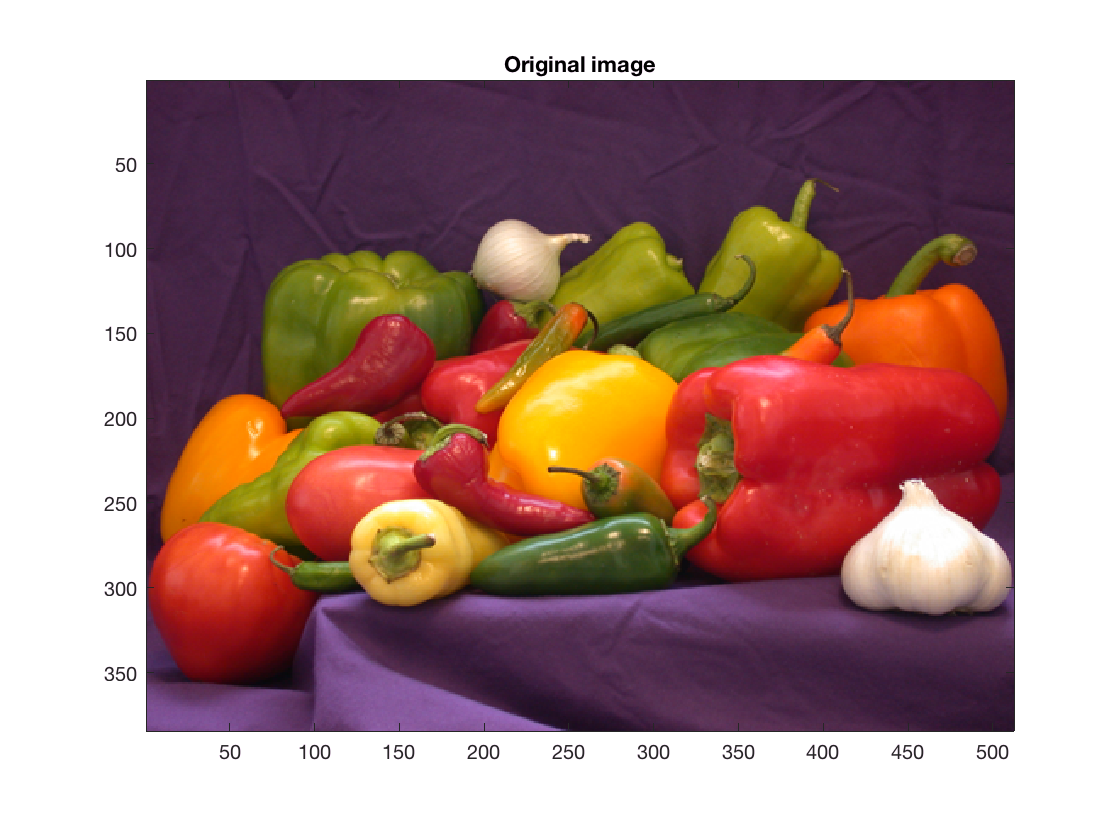

close all;
img = imread('peppers.png');
img = double(img);
img = img/max(img(:));

d = 4;
figure;imagesc(img);axis image;
title("Original image");

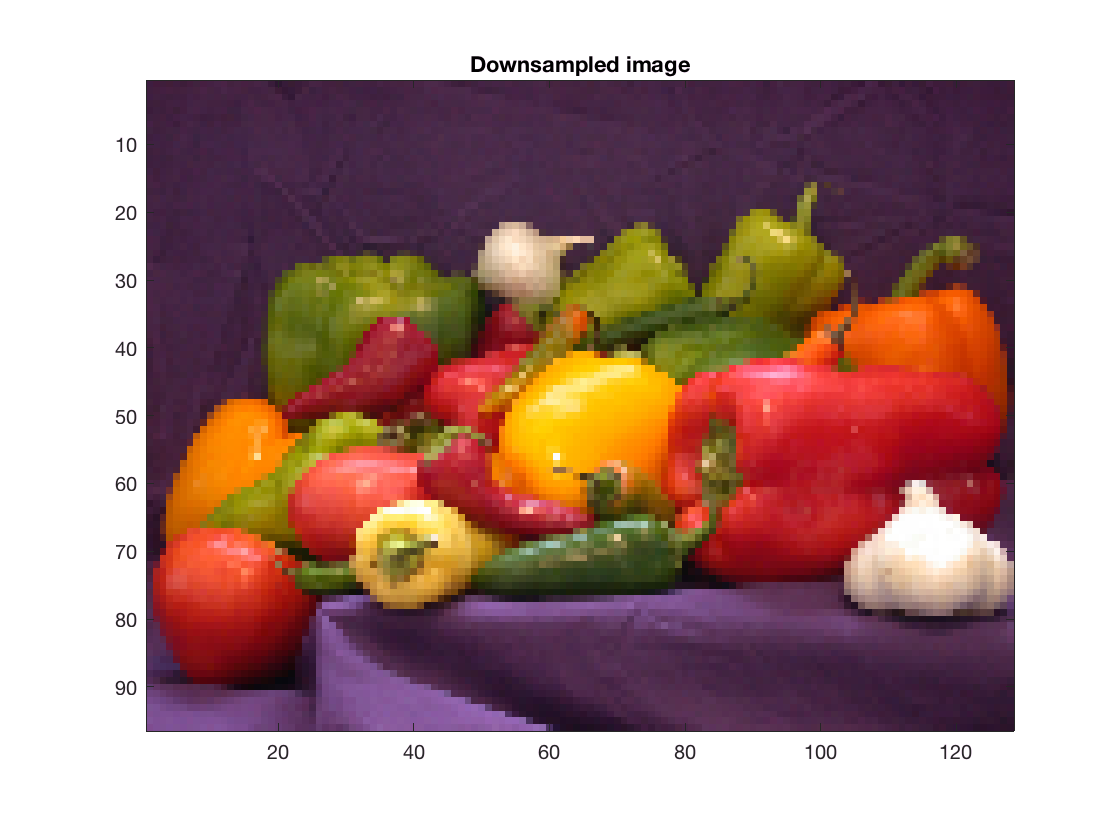

figure;imagesc(img(1:d:end,1:d:end,:));axis image;
title("Downsampled image");

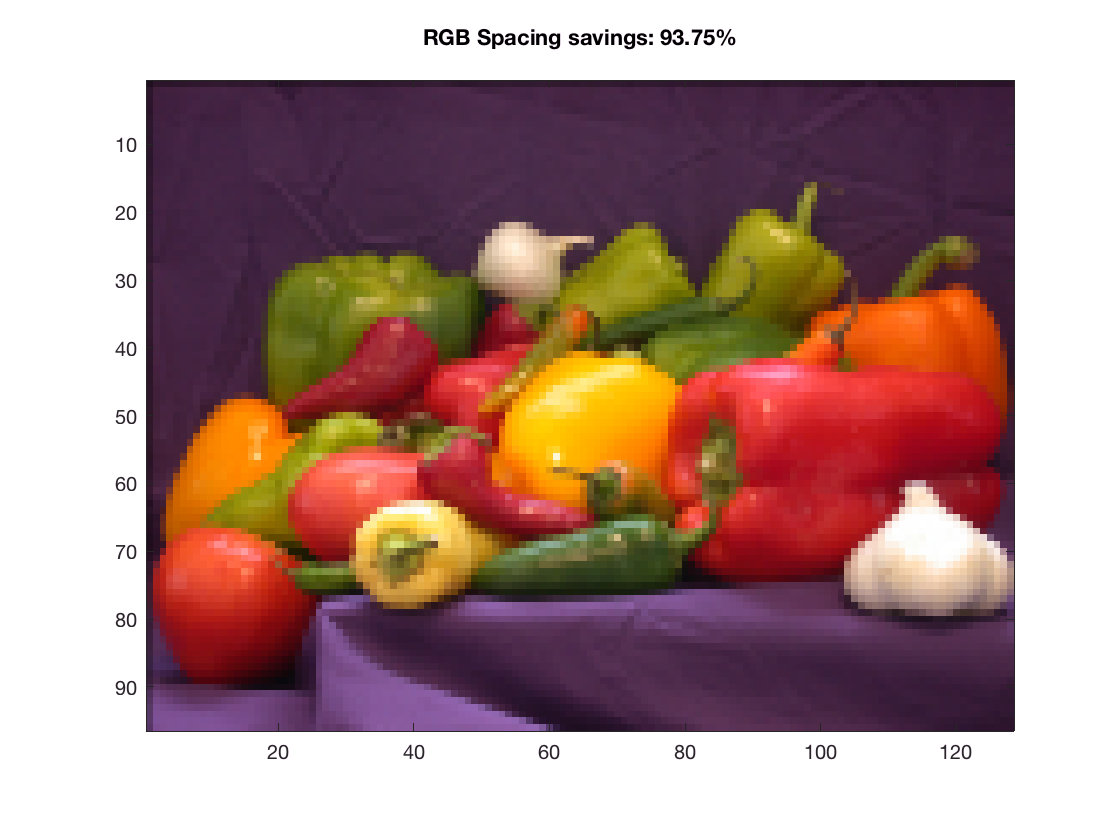


imgS = convn(img,fspecial('Gaussian',[15 15],1),'same');
figure;imagesc(imgS(1:d:end,1:d:end,:));axis image;
title(sprintf('Downsampled image: RGB Spacing savings: %2.2f%%\n',100-100*(1/(d^2))))

## Image Pyramid

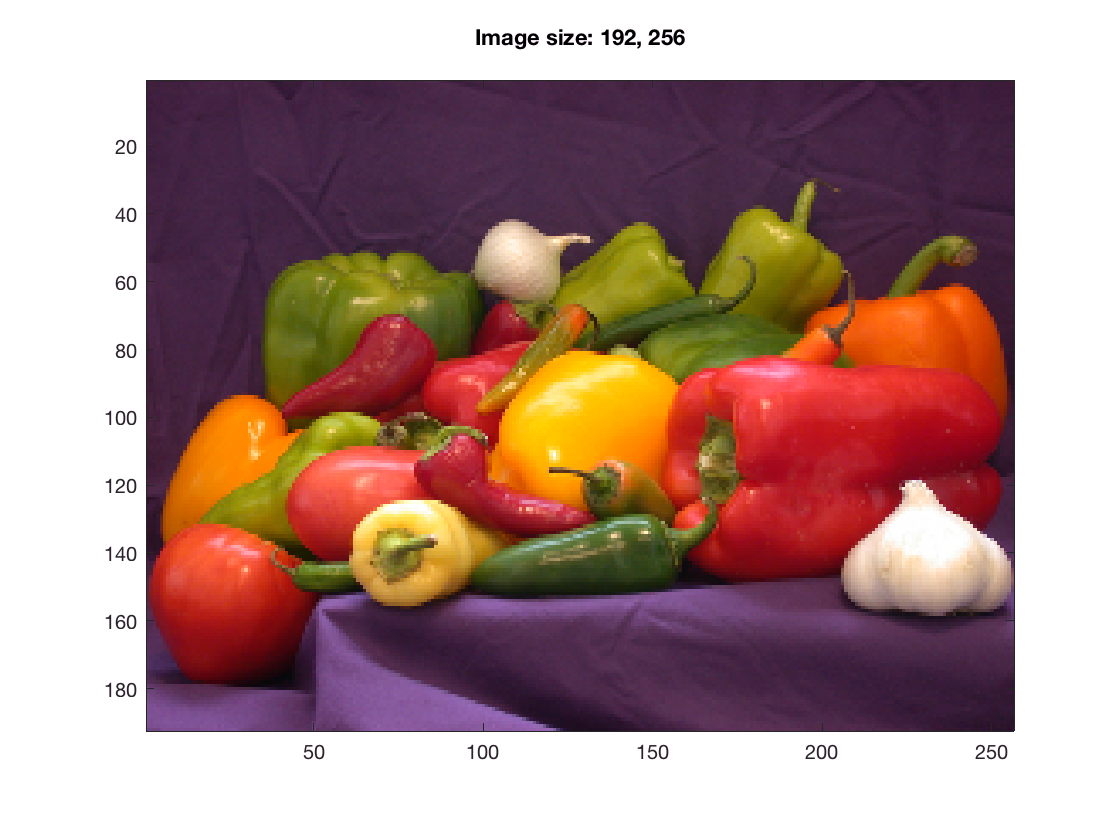

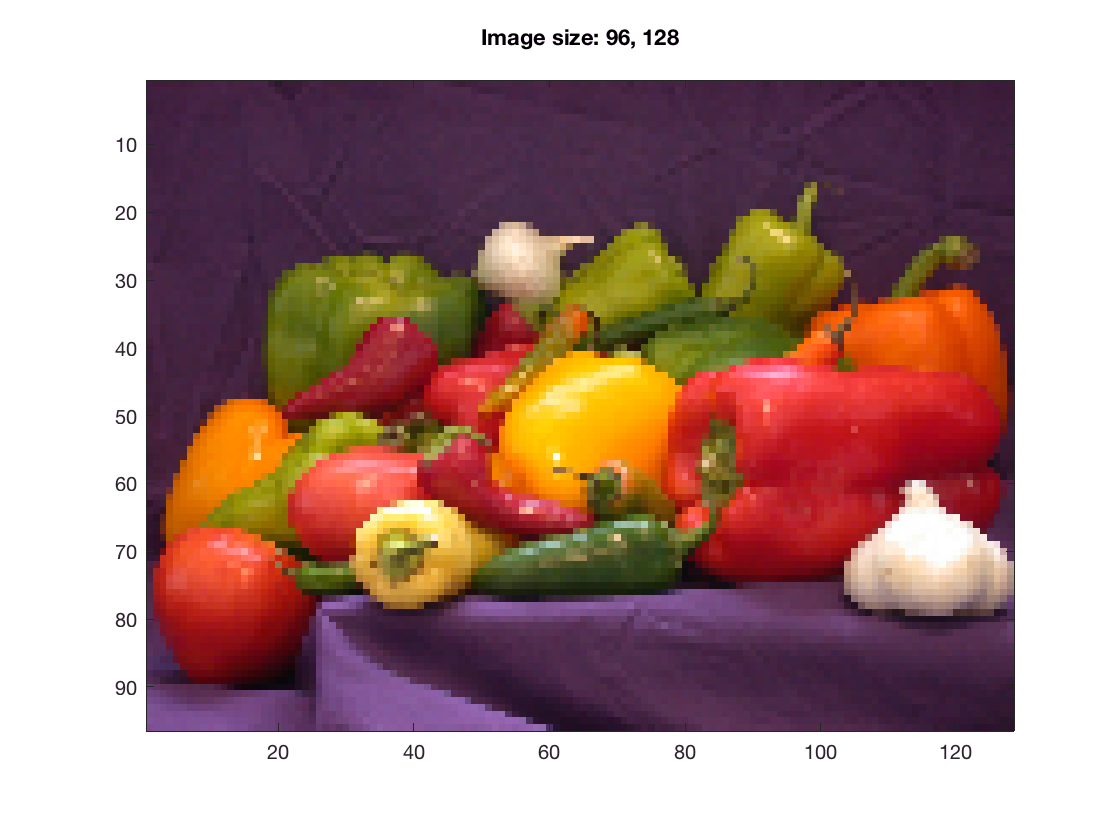

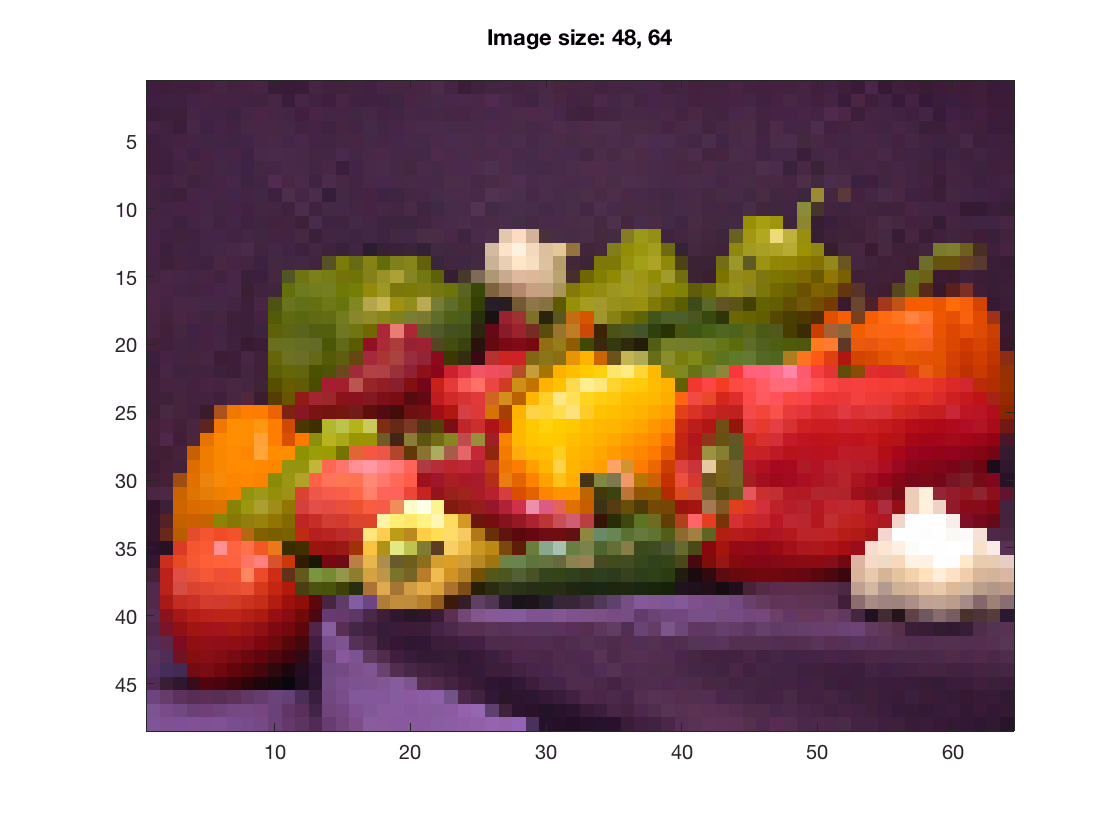

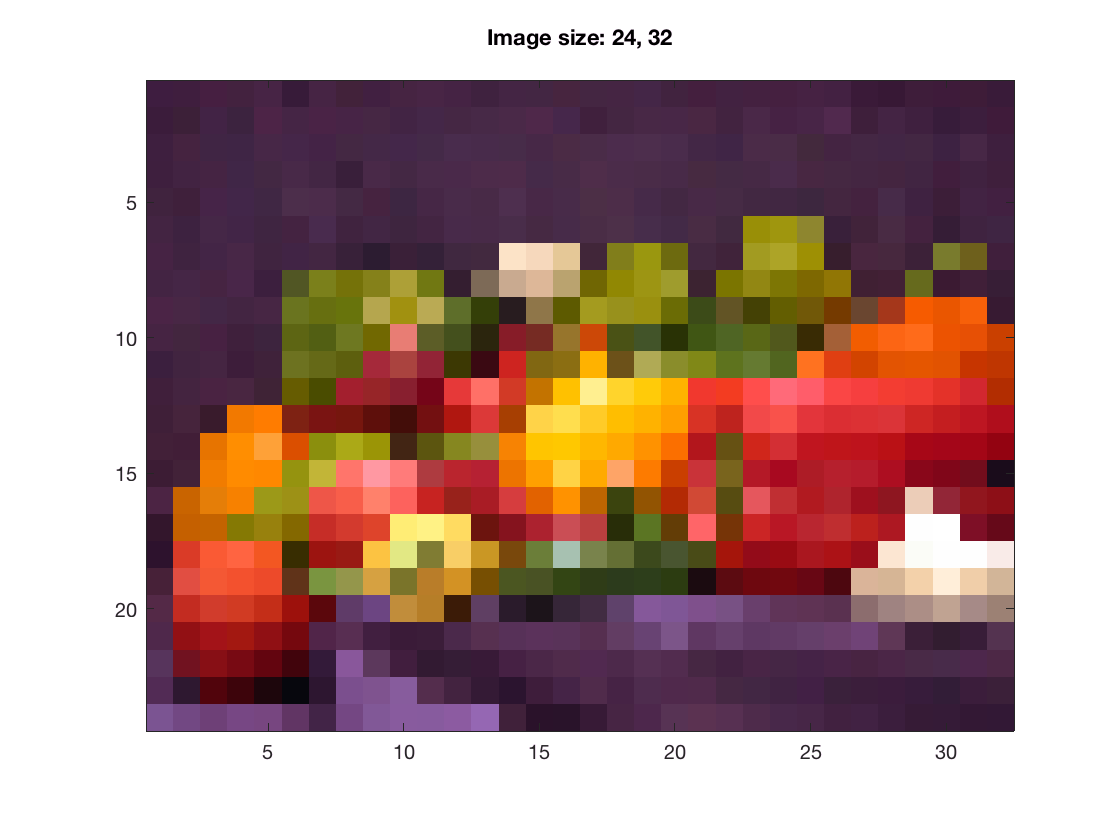

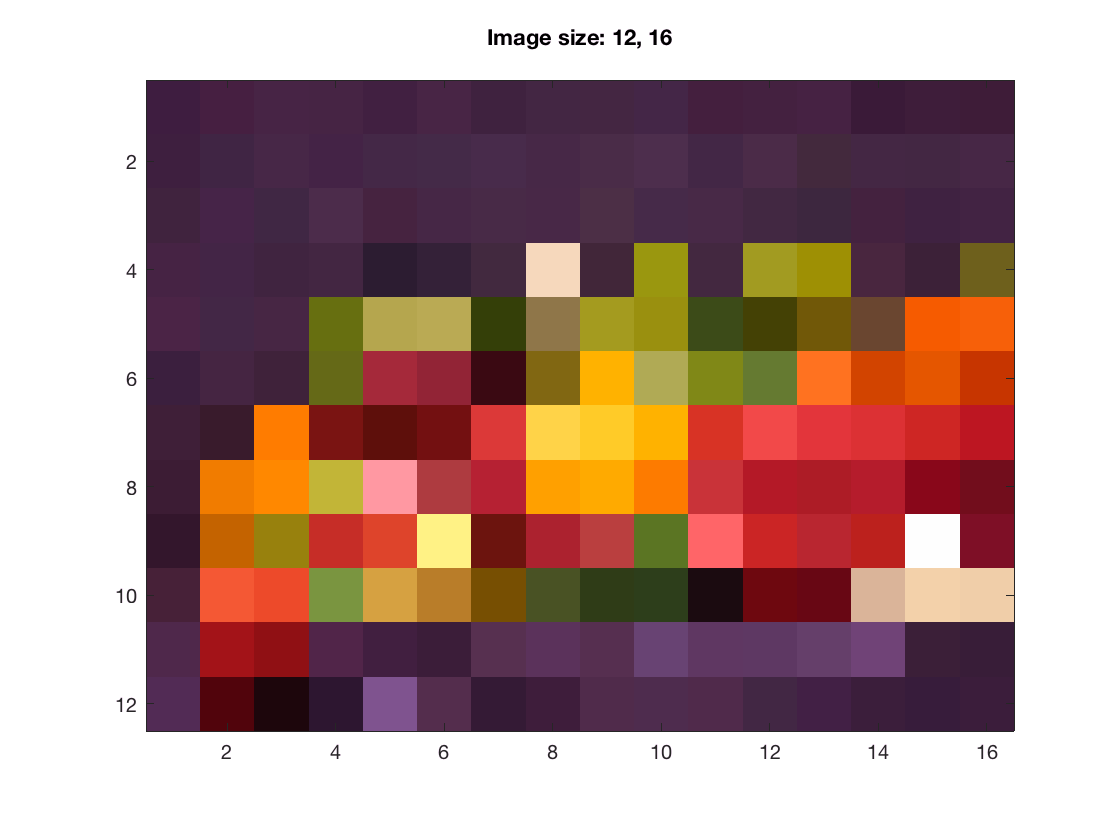

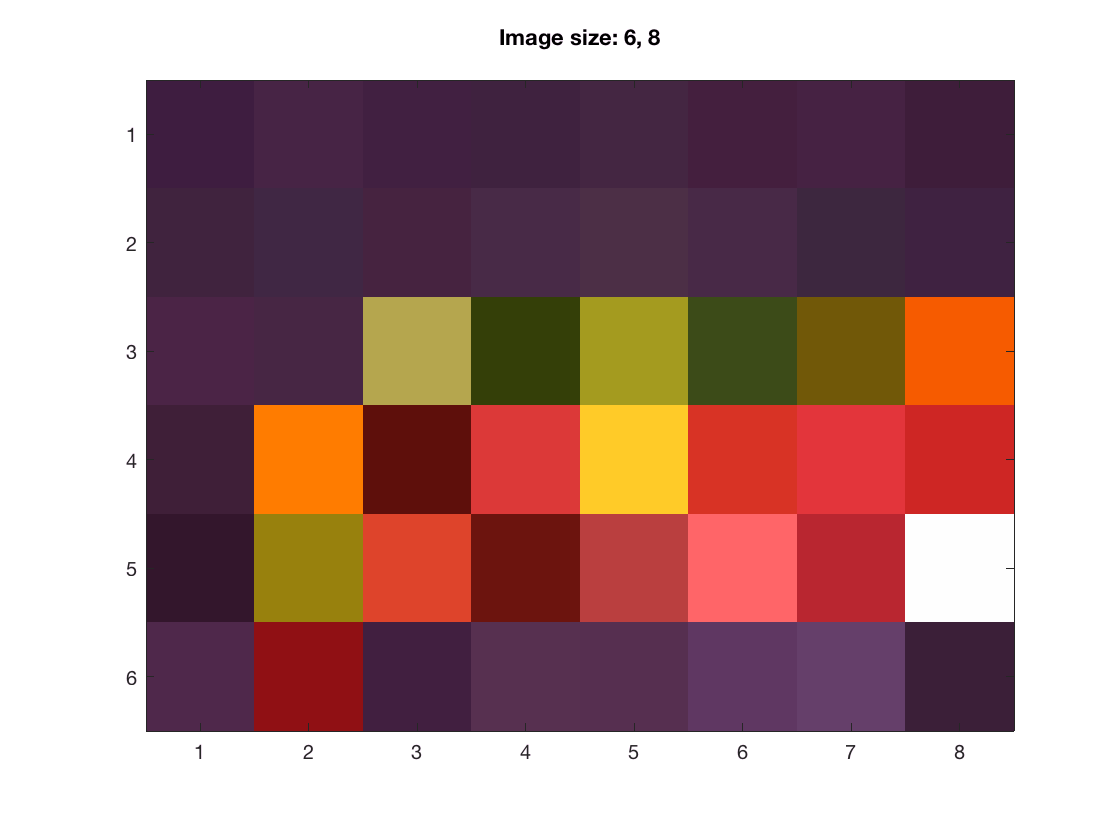

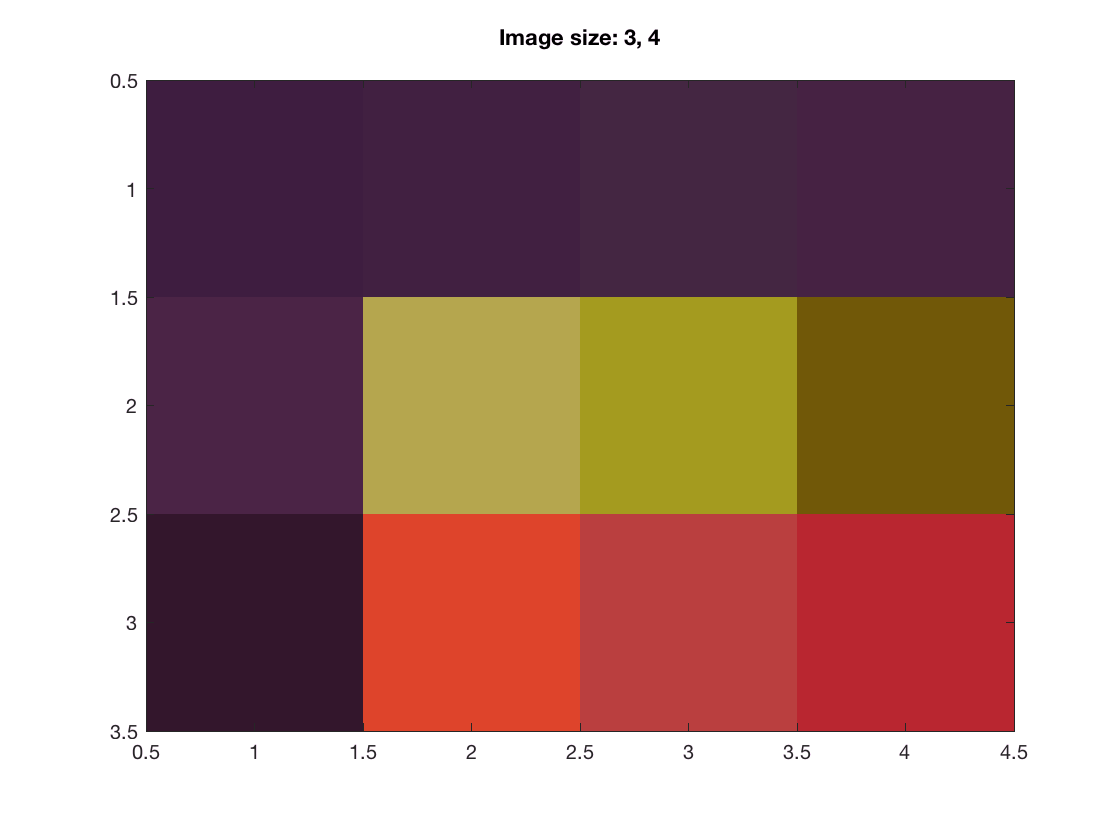

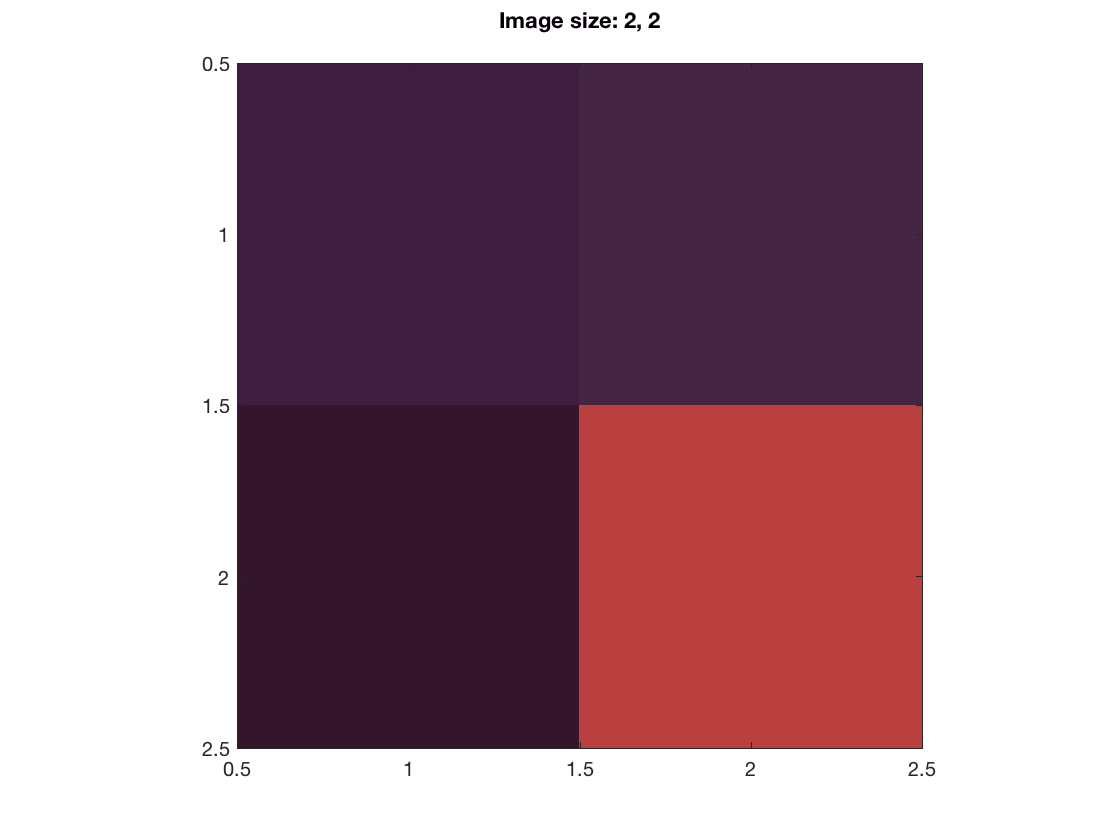

close all;
imgSub = img;
imSize = size(img);
for d=1:ceil(log2(min(imSize(1:2))))
    imgS = convn(imgSub,fspecial('Gaussian',[15 15],1),'same');
    imgSub = imgSub(1:2:end,1:2:end,:);
    figure;imagesc(imgSub);axis image;
    title(sprintf('Image size: %i, %i\n',size(imgSub,1),size(imgSub,2)));
    %pause;
end

## Corner detection - using built-in functions.

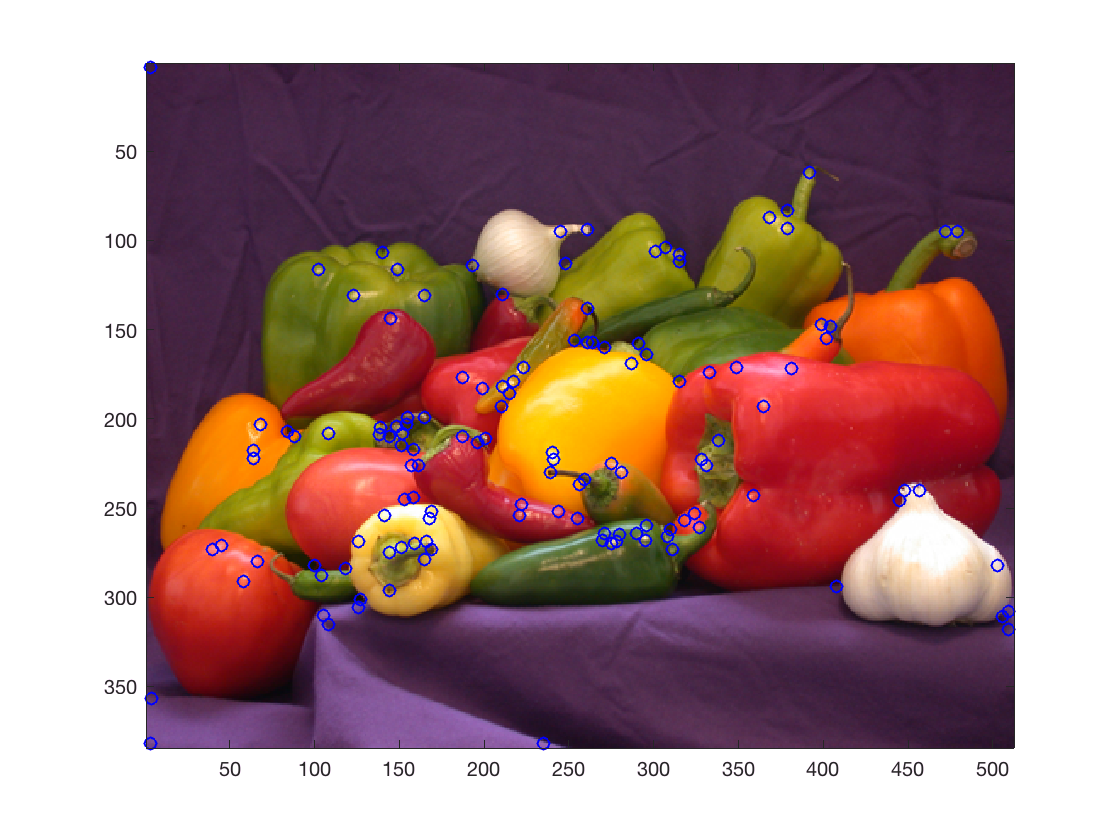

close all;
sigma = 2;
imgS = convn(img,fspecial('Gaussian',[25 25],sigma),'same');
cornerness = cornermetric(mean(imgS,3));
d = corner(mean(imgS,3));
figure;imagesc(img);hold on;plot(d(:,1),d(:,2),'bo');

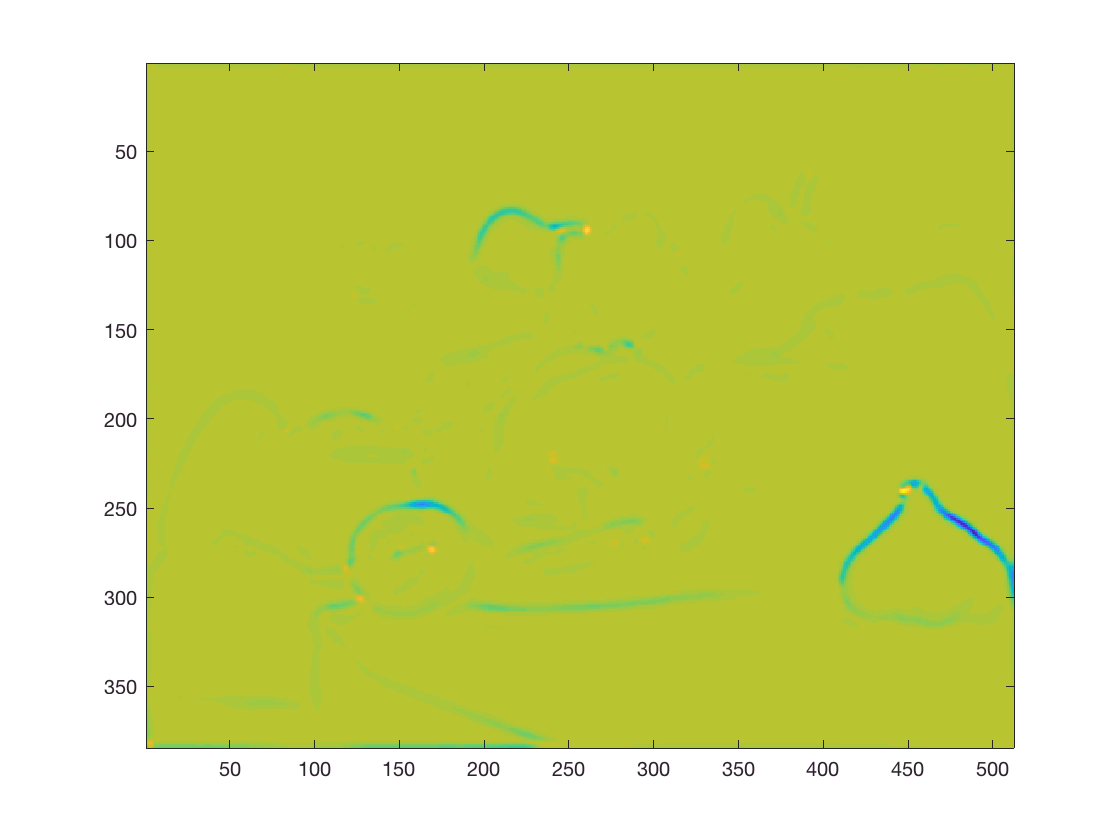

title("Detected corners");

figure;imagesc(cornerness);

title("Cornerness function");


## Corner detection on a noisy image

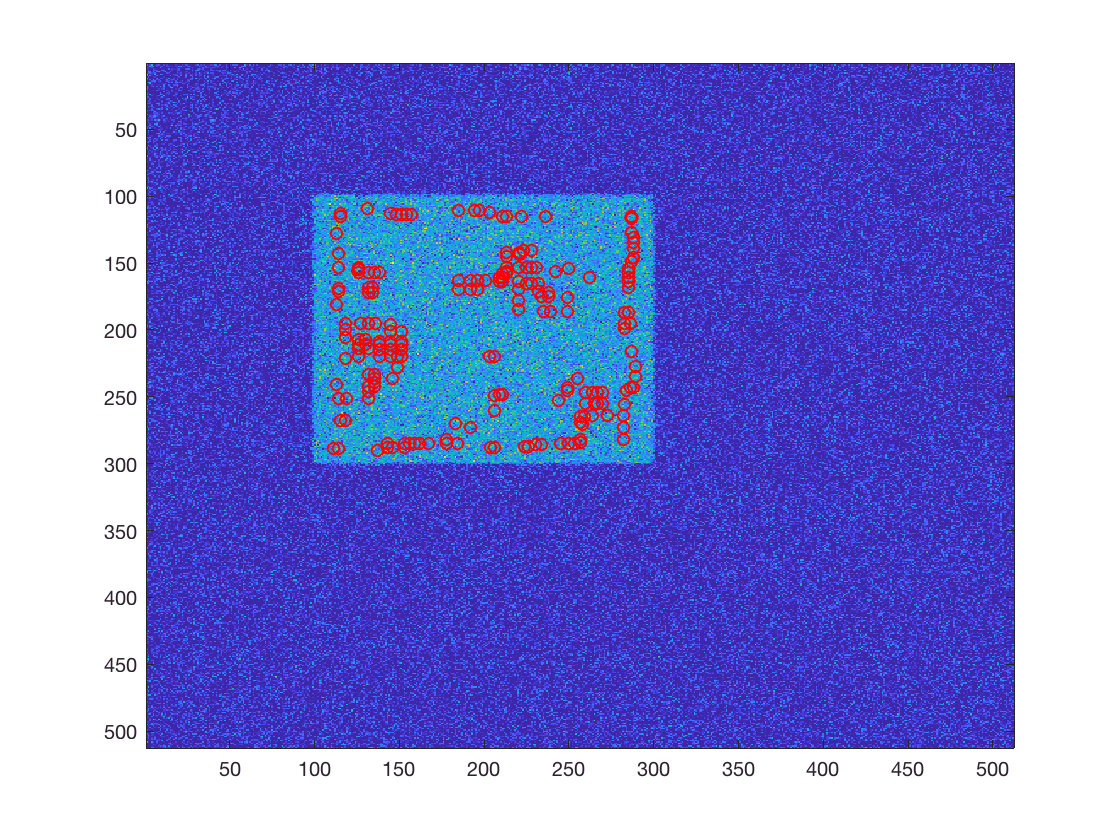

close all;
img = zeros(512,512);
img(100:300,100:300)=100;
img = conv2(img,fspecial('Gaussian',[10 10],1),'same');%make the corners a bit rounded
sd = 40;%How do the corners behave as we increase the noise?
img = img+sd*randn(size(img));
img(img<0)=0;

%This is a different smoothing step than the window function, w.
sigma = 1;
imgS = conv2(img,fspecial('Gaussian',[25 25],sigma),'same');

sigmaW =16;%How do the corners move as we increase sigma or sigmaW?
w = fspecial('Gaussian',[1 45],sigmaW);
cornerness = cornermetric(imgS,'harris','FilterCoefficients',w);
d = corner(imgS,'harris','FilterCoefficients',w,'QualityLevel',0.4);
figure;imagesc(img);hold on;plot(d(:,1),d(:,2),'ro');

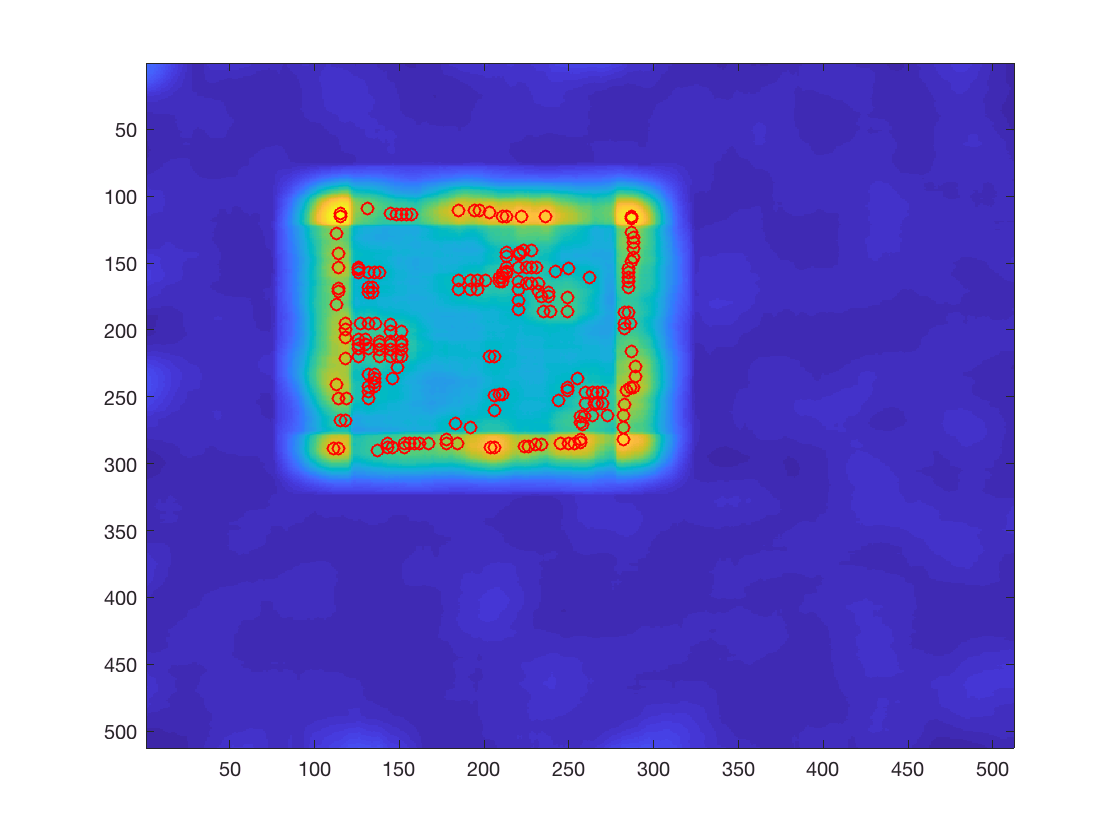

figure;imagesc(cornerness);hold on;plot(d(:,1),d(:,2),'ro');